% Последовательная LR-цепь подключена к пост. напр. U=100 В
clear
R_uz=10; % Ом
L_uz=0.2; % Гн
U_uz=100; % В
% i_L(t), u_L(t) - ?

% 3. Составляем уравнение по 2-му закону Кирхгофа
syms t u_L(t) u_R(t) i(t) U L R
u_L+u_R-U==0                           % (6.6)

$$ans(t) = u_{L}\left(t\right)-U+u_{R}\left(t\right)=0$$

eq1=L*diff(i)+R*i-U

$$eq1(t) = L\,\frac{\partial }{\partial t}i\left(t\right)-U+R\,i\left(t\right)$$

cond=i(0)==0

$$cond = i\left(0\right)=0$$

i_L=dsolve(eq1,cond)

$$i\_L = \frac{U-U\,{\mathrm{e}}^{-\frac{R\,t}{L}}}{R}$$

i_L=subs(i_L,[U R L],[U_uz R_uz L_uz])                % (6.10)

$$i\_L = 10-10\,{\mathrm{e}}^{-50\,t}$$

u_L=U-u_R

$$u\_L(t) = U-u_{R}\left(t\right)$$

u_L=U-R*i

$$u\_L(t) = U-R\,i\left(t\right)$$

u_L=subs(u_L,[U R i],[U_uz R_uz i_L])             % (6.11)

$$u\_L(t) = 100\,{\mathrm{e}}^{-50\,t}$$

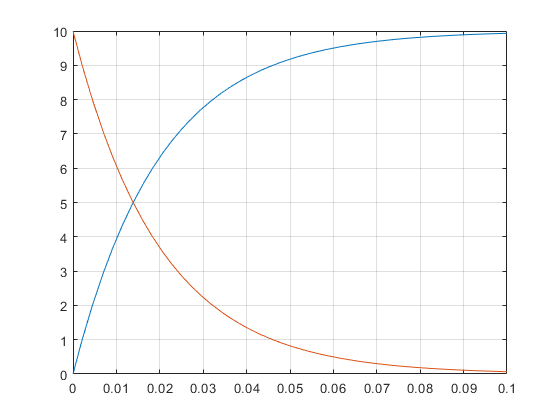

fplot(i_L)
hold on
fplot(u_L/10)
grid
hold off
xlim([0,0.1])